#### THIS SCRIPT ASSUMES YOU HAVE ALREADY DOWNLOADED AND EXTRACTED THE DATA SET FROM THE[ PHYSIONET CHALLENGE PAGE](https://archive.physionet.org/pn3/challenge/2016/). USE THIS[ LINK ](https://archive.physionet.org/pn3/challenge/2016/)IF YOU NEED TO DOWNLOAD THE DATASET.  

Add current folder and subfolders to search path, so the script can find the recordings in subdirectories of "Data", and various MATLAB functions in "HelperFunctions".

addpath(genpath(pwd));
addpath('./HelperFunctions');
warning off;                      % suprress warning messages

## Prepare to read the data into memory

To load the recordings into memory, MATLAB's [fileDatastore](https://www.mathworks.com/help/matlab/ref/filedatastore.html) provides a convenient way to handle a large number of data files spread across multiple folders. The read function provides flexibility to access a wide variety of different file formats, and with MATLAB's base read functions typically little customization is needed. 

% expecting the training data in subfolders of 'Data\training\*': "training-a", etc
training_fds = fileDatastore(fullfile(pwd, 'Data', 'training'), 'ReadFcn', @importAudioFile, 'FileExtensions', '.wav','IncludeSubfolders',true);

## Create a table with filenames and labels

"Labels" (or also "ground truth") represent the true category of each sample in a dataset and are critical to be able to apply  "supervised" machine learning to this classification task. The dataset we are using here provides the labels in a separate REFERENCE file in each subfolder of the training and validation data, along with the corresponding audio files (recordings). So in this section we read these REFERENCE.csv files and build a table with filename and corresponding label. This step is only needed if you want to run feature extraction in the next step.

data_dir = fullfile(pwd, 'Data', 'training');
folder_list = dir([data_dir filesep 'training*']);

reference_table = table();

for ifolder = 1:length(folder_list)
    disp(['Processing files from folder: ' folder_list(ifolder).name])
    current_folder = [data_dir filesep folder_list(ifolder).name];
    
    % Import ground truth labels (1, -1) from reference. 1 = Normal, -1 = Abnormal
    reference_table = [reference_table; importReferencefile([current_folder filesep 'REFERENCE.csv'])];
end

## 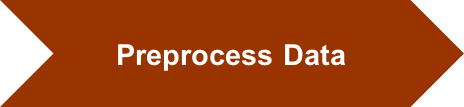

## Extract features from raw heart sound signals

Next we need to extract features from the raw recordings. We use statistical and signal processing functions available in MATLAB to process and extract features from the raw heart sound signal. The following section extracts some 27 features for each recording, and splits each recording into windows consisting of 5 seconds of heart sound.

runExtraction = false; % control whether to run feature extraction (will take several minutes)
   % Note: be sure to have the training data downloaded before executing
   % this section!
if runExtraction | ~exist('FeatureTable.mat')%#ok 
    % Window length for feature extraction in seconds
    win_len = 5;
    
    % Specify the overlap between adjacent windows for feature extraction in percentage
    win_overlap = 0;
    
    % Initialize feature table to accumulate observations
    feature_table = table();
    
    % Use Parallel Computing Toobox to speed up feature extraction by distributing computation across available processors
    
    % Create partitions of the fileDatastore object based on the number of processors
    n_parts = numpartitions(training_fds, gcp);
    
    % Note: You could distribute computation across available processors by using 
    % parfor instead of "for" below, but you'll need to omit keeping track
    % of signal lengths
    parfor ipart = 1:n_parts
        % Get partition ipart of the datastore.
        subds = partition(training_fds, n_parts, ipart);
        
        % Extract features for the sub datastore
        [feature_win,sampleN] = extractFeatures(subds, win_len, win_overlap, reference_table);
        
        % and append that to the overall feature table we're building up
        feature_table = [feature_table; feature_win];
        
        % Display progress
        disp(['Part ' num2str(ipart) ' done.'])
    end
    save('FeatureTable', 'feature_table');

else % simply load the precomputed features
    load('FeatureTable.mat');
end

## **Train the classifier  with misclassification cost**

% Assign higher cost for misclassification of abnormal heart sounds
C = [0, 10; 1, 0];        

% Create a random sub sample (to speed up training) of 1/4 of the training set
%subsample = randi([1 height(training_set)], round(height(training_set)/4), 1);
% OR train on the whole training set
subsample = 1:height(training_set);

rng(1);

% Create a 10-fold cross-validation set from training data
cvp = cvpartition(length(subsample),'KFold',10);

% Step 2: train the model with hyperparameter tuning (unless you simply
% load an existing pre-trained model)

% train ensemble of decision trees (random forest)
disp("Training Ensemble classifier...")

    
% bayesian optimization parameters (stop after 15 iterations)
opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',20);    
trained_model = fitcensemble(training_set(subsample,:),'class','Cost',C,...
        'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'},...
        'HyperparameterOptimizationOptions',opts)


## **Perform feature selection using Neighborhood Component Analysis**

runNCA = true;   % control whether to see NCA running or just load the selected features
    
if ~runNCA && exist('SelectedFeatures.mat')%#ok
    % Load saved array of selected feature indexes
    load('SelectedFeatures.mat')
else % Perform feature selection with neighborhood component analysis
    rng(1);
    
    % first, let's make sure we've split the data (in case we skipped the
    % programmatic model training sections above)
    if ~exist('training_set')
        [training_set, test_set] = splitDataSets(train_feature_table_1,0.3);
    end
    
    mdl = fscnca(table2array(training_set(:,1:27)), ...
        table2array(training_set(:,28)), 'Lambda', 0.005, 'Verbose', 0);
    
    % Select features with weight above 1
    selected_feature_indx = find(mdl.FeatureWeights > 0.1);

    % Plot feature weights
    stem(mdl.FeatureWeights,'bo');
    
    % save for future reference
    save('SelectedFeatures', 'selected_feature_indx');
end

## **Train model with selected features**

trainReducedModel = false;    % control whether to re-train this model or load it from a previous run

if trainReducedModel | ~exist('TrainedEnsembleModel_FeatSel.mat')%#ok
    % configure key parameters: cross validation, cost, and hyperparameter
    % tuning
    rng(1)
    cvp = cvpartition(length(subsample),'KFold',10);
    C = [0, 10; 1, 0];            % Assign higher cost for misclassification of abnormal heart sounds
    opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',20);    
    
    % now we are ready to train...
    trained_model_featsel = fitcensemble(training_set(subsample,selected_feature_indx),training_set.class(subsample),'Cost',C,...
        'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'}, 'HyperparameterOptimizationOptions',opts)
    % save the model for later reference
    save('TrainedWaveletModel_FeatSel', 'trained_model_featsel');
else
    load('TrainedEnsembleModel_FeatSel.mat')
end

# Testing a Random Audio File

classifyHeartSounds_ensemble(signal, sampling freq)